# **JacobiNC**

[Jacobi elliptic function nc](https://dlmf.nist.gov/22)

## Definition


$$\mathrm{nc}\left(x\left|m\right.\right)\equiv \frac{1}{\mathrm{cn}\left(x\left|m\right.\right)}$$



$$\mathrm{nc}\left(x,k\right)\equiv \mathrm{nc}\left(x\left|k^2 \right.\right)$$


where *m *is the parameter, *k *is the modulus, and  cn is Jacobi elliptic functionc function.

Domain: $-\infty <x<\infty$, $-\infty <m<\infty$. For the specified domain, the  codomain of nc is the set of real numbers.

Basic features:

$\mathrm{nc}\left(x+4K\left(m\right)\left|m\right.\right)=\mathrm{nc}\left(x\left|m\right.\right)$  (periodic) ,  $\mathrm{nc}\left(-x\left|m\right.\right)=\mathrm{nc}\left(x\left|m\right.\right)$ (even)

Special values:


$$\mathrm{nc}\left(0\left|m\right.\right)=1$$


$\mathrm{nc}\left(x\left|0\right.\right)=1/\mathrm{cos}\;x$,  $\textrm{nc}\left(x\left|1\right.\right)=\textrm{co}\mathrm{sh}\;x$

Identities:


$$\mathrm{nc}\left(x\left|m\right.\right)=\mathrm{nd}\left(x\sqrt{m}\left|m^{-1} \right.\right)$$


## Syntax

Y = JacobiNC(X,K)

y = jnc(x,k)

Y = mJacobiNC(X,M)

y = mjnc(x,m)

## Dencription

Y = JacobiNC(X,K) returnc the Jacobi elliptic function $\mathrm{nc}\left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the same size or any of them can be ncalar. **JacobiNC** is the wrapper function which calls the functionc **jnc** element-wise via the function **ufun2**.

y = jnc(x,k) returnc the Jacobi elliptic function $\mathrm{nc}\left(x,k\right)$ for argument x and the modulus k. It is assumed that  arguments are real ncalars without check. The function returnc NaN if either of  the arguments is invalid or convergence failed. **jnc** calls the functionc **sncndn **for calculation of$\;\mathrm{nc}\left(x,k\right)$ .

Y = mJacobiNC(X,M) returnc the Jacobi elliptic function $\mathrm{nc}\left(x\left|m\right.\right)$ for each element of the arrays X and M (parameter). X and M must be real and the same size or any of them can be ncalar. **mJacobiNC** is the wrapper function which calls the function **mjnc** element-wise via the function **ufun2**.

y = mjnc(x,m) returnc the Jacobi elliptic function $\mathrm{nc}\left(x\left|m\right.\right)$ for  argument x and the parameter m. It is assumed that  arguments are real ncalars without check. The function returnc NaN if either of  the arguments is invalid or convergence failed.  **mjnc** calls the functionc **sncndn **for calculation of $\mathrm{nc}\left(x\left|m\right.\right)$ .

**sncndn **implements the AGM trancformation for simultaneously  computation of the functionc *sn*, *cn*, *dn* . For $m>1$ the Jacobi's transformation is used [1,2].

## Precision

## **Numerical Examples**

**Salar input**

format long
k = 0.5; 
x = 0.5;
[jnc(x,k), JacobiNC(x,k), mjnc(x,k^2), mJacobiNC(x,k^2)]

ans =    1.136439799830979   1.136439799830979   1.136439799830979   1.136439799830979


Accuracy

fprintf('%.16g\n',jnc(3,5))

1.011789081114261


% Maple 1.011789081114260_72

[MATLAB example](https://www.mathworks.com/help/symbolic/jacobinc.html)

disp(mJacobiNC([2 1 -3],[1 2 3]))

   3.762195691083631   1.350514283678651   1.224738474169702



fprintf('%.16g\n',mjnc(3,5))

1.000485351724092


% MATLAB 1.000485351724092_2102007985618873


Identities

x=2;
m = 0.12; % m > 0
disp(mjnc(x,m)-mjnd(x*sqrt(m),1/m))

     0



**Vector input**

X=[1 2 3 4];
disp(JacobiNC(X,0)-1./cos(X))

     0     0     0     0



X=[1 2 3 4];
disp(JacobiNC(X,1)-cosh(X))

   1.0e-14 *

                   0  -0.044408920985006                   0   0.355271367880050



m = 0.12; 
disp(mJacobiNC(X,m)-mJacobiND(X*sqrt(m),1/m))

   1.0e-15 *

                   0                   0  -0.222044604925031                   0



**Matrix input**

X=[1 2; 3 4];
disp(JacobiNC(X,1)-cosh(X))

   1.0e-14 *

                   0  -0.044408920985006
                   0   0.355271367880050



M = [1 2; 0.2 0.3]; 
disp(mJacobiNC(X,M)-mJacobiND(X.*sqrt(M),1./M))

     0     0
     0     0



## **Graphs **

**Example 1**

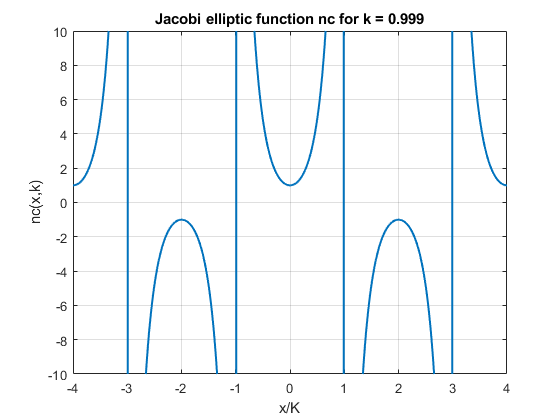

figure
x=-4:0.01:4;
k = 0.999;
K = elK(k);
plot(x,JacobiNC(x*K,k),'LineWidth',1.5)
xlabel('x/K')
ylabel('nc(x,k)')
ylim([-10 10])
title(sprintf('Jacobi elliptic function nc for k = %g',k))
grid on

**Example 2**

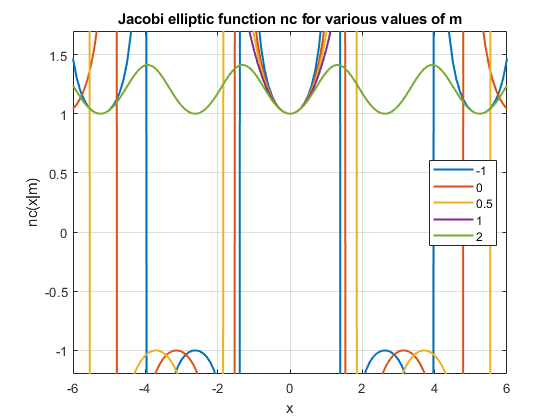

figure
X = -6:0.1:6;
M = [-1,0,0.5,1,2];
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mJacobiNC(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) -1.2 1.7])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Jacobi elliptic function nc for various values of m')
xlabel('x')
ylabel('nc(x|m)')

**Example 3**

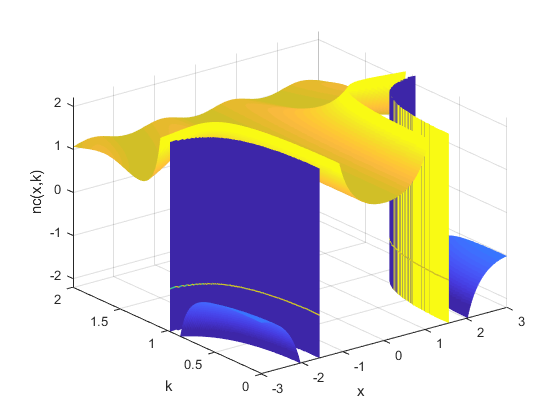

figure
x=-3:0.01:3;
k=0:0.01:2;
[X,K]=meshgrid(x,k);
hs=surfc(X,K,JacobiNC(X,K),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -1.2;
hc.LineWidth = 1;
hc.LevelList = 0:0.1:1;
caxis([-2 2])
view(3);
xlabel('x')
ylabel('k')
zlabel('nc(x,k)')
zlim([-2.2 2.2])
grid on

**Example 4**

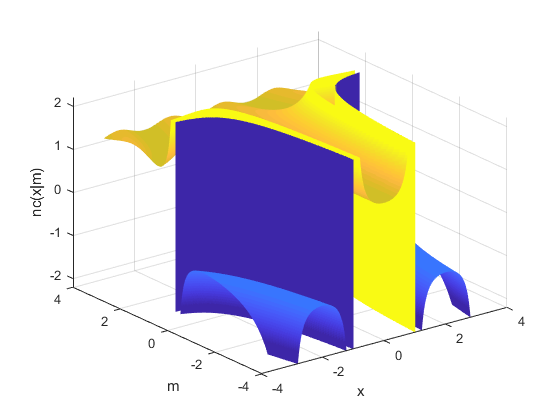

figure
x=-3:0.01:3;
m=-4:0.01:4;
[X,M]=meshgrid(x,m);
surface(X,M,mJacobiNC(X,M),'EdgeColor','none')
view(3)
caxis([-2 2])
xlabel('x')
ylabel('m')
zlabel('nc(x|m)')
zlim([-2.2 2.2])
grid on

**Example 5**

[MATLAB example](https://www.mathworks.com/help/symbolic/jacobinc.html)

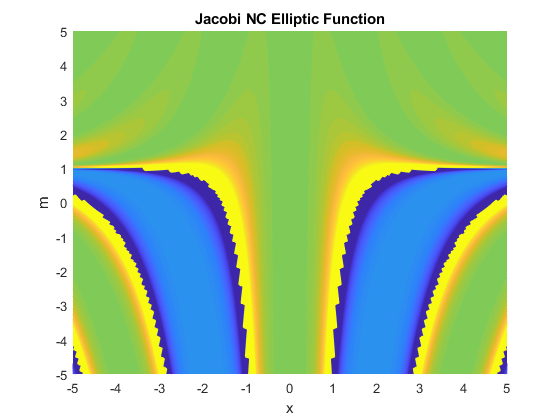

figure
f = @(x,m)mJacobiNC(x,m);
fcontour(f,'Fill','on') %,'LevelList',-3:0.1:3,'MeshDensity',200)
title('Jacobi NC Elliptic Function')
xlabel('x')
ylabel('m')

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functionc](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functionc, NIST Digital Library of Mathematical Functionc](https://dlmf.nist.gov/22)

[Jacobi elliptic functionc, Wikipedia](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions)

## **References**

[1] R. Bulirnch, Numerical Calculation of Elliptic Integrals and Elliptic Functionc. Numerinche Mathematik 7, 78-90, 1965

[2] W.H. Press et al., Numerical Recipes, 3rd ed., Cambridge, 2007

## See Also